clear all;
close all;
clc;
 
% ROS data
FBTC = readtable('FBTC_8shape_data.csv'); % For a CSV with headers
FBSMC = readtable('FBSMC_8shape_data.csv'); % For a CSV with headers
  
% read data
t_fbtc=FBTC{1:4697,1};
x_fbtc=FBTC{1:4697,2};
y_fbtc=FBTC{1:4697,3};
theta_rad_fbtc=FBTC{1:4697,4};
theta_deg_fbtc=FBTC{1:4697,5};
v_fbtc=FBTC{1:4697,6};
w_fbtc=FBTC{1:4697,7};

t_FBSMC=FBSMC{1:4697,1};
x_FBSMC=FBSMC{1:4697,2};
y_FBSMC=FBSMC{1:4697,3};
theta_rad_FBSMC=FBSMC{1:4697,4};
theta_deg_FBSMC=FBSMC{1:4697,5};
v_FBSMC=FBSMC{1:4697,6};
w_FBSMC=FBSMC{1:4697,7};


## Theta reference plotting

A=1;
B=-1;
w=0.04;
x_d=[A*sin(w*t_FBSMC);B*sin(2*w*t_FBSMC)];   % coordinates of the desired position 
xdot_d=[A*w*cos(w*t_FBSMC);B*2*w*cos(2*w*t_FBSMC)];
theta_ref = atan(xdot_d(2,:) ./ xdot_d(1,:));

## Results plotting in subplot

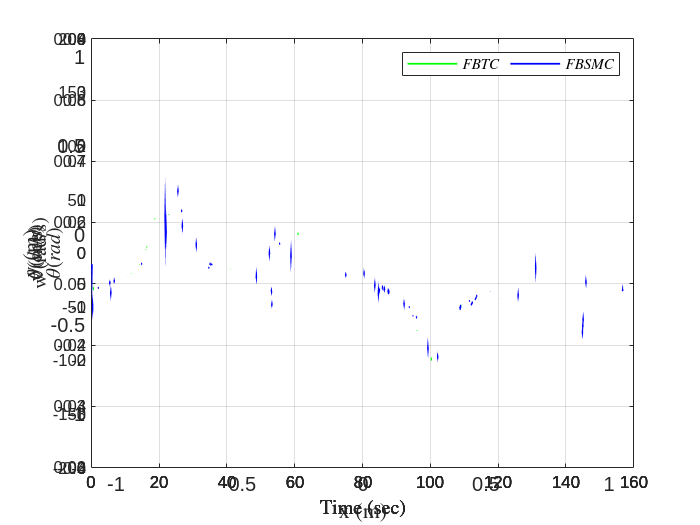


figure(1);
axes('fontsize',12)
plot(x_fbtc,y_fbtc,'g',x_FBSMC,y_FBSMC,'b',1.*sin(0.04.*t_FBSMC),-1.*sin(0.08.*t_FBSMC),'--r','Linewidth',2);
legend('$FBTC$','$FBSMC$','Ref','fontsize',12,'interpreter','latex','Location','southwest','NumColumns', 3)
xlabel('${\mathrm{x}}$ $\mathrm{(m)}$','fontsize',12,'interpreter','latex')
ylabel('${\mathrm{y}}$ $\mathrm{(m)}$','fontsize',12,'interpreter','latex')
set(gca,'fontsize',12,'Xlim',[-1.1 1.1],'Ylim',[-1.3 1.1])
set(gca,'XGrid','on', 'YGrid','on','GridLineStyle','-');

figure(3);
axes('fontsize',12)
plot(t_fbtc,theta_rad_fbtc,'g',t_FBSMC,theta_rad_FBSMC,'b',t_FBSMC,theta_ref,'r--','Linewidth',2); % for nominal control
legend('$FBTC$','$FBSMC$','$Ref$','interpreter','latex','Location','northeast','NumColumns', 3)
ylabel('$\theta(rad)$','fontsize',12,'interpreter','latex')
xlabel('$\mathrm{Time}$ $\mathrm{(sec)}$','fontsize',12,'interpreter','latex')
set(gca,'XGrid','on', 'YGrid','on','GridLineStyle','-');


figure(4);
axes('fontsize',12)
plot(t_fbtc,theta_deg_fbtc,'g',t_FBSMC,theta_deg_FBSMC,'b','Linewidth',1); % for nominal control
legend('$FBTC$','$FBSMC$','interpreter','latex','Location','northeast','NumColumns', 2)
ylabel('$\theta(deg)$','fontsize',12,'interpreter','latex')
xlabel('$\mathrm{Time}$ $\mathrm{(sec)}$','fontsize',12,'interpreter','latex')
set(gca,'XGrid','on', 'YGrid','on','GridLineStyle','-');

figure(5);                     
axes('fontsize',12)
plot(t_fbtc,v_fbtc,'g',t_FBSMC,v_FBSMC,'b','Linewidth',1); % for nominal control
legend('$FBTC$','$FBSMC$','interpreter','latex','Location','northeast','NumColumns', 2)
ylabel('${\mathrm{v}}$ $\mathrm{(m/s)}$','fontsize',12,'interpreter','latex')
xlabel('$\mathrm{Time}$ $\mathrm{(sec)}$','fontsize',12,'interpreter','latex')
set(gca,'XGrid','on', 'YGrid','on','GridLineStyle','-');

figure(6);                     
axes('fontsize',12)
plot(t_fbtc,w_fbtc,'g',t_FBSMC,w_FBSMC,'b','Linewidth',1); % for nominal control
legend('$FBTC$','$FBSMC$','interpreter','latex','Location','northeast','NumColumns', 2)
ylabel('${\mathrm{w}}$ $\mathrm{(rad/s)}$','fontsize',12,'interpreter','latex')
xlabel('$\mathrm{Time}$ $\mathrm{(sec)}$','fontsize',12,'interpreter','latex')
set(gca,'XGrid','on', 'YGrid','on','GridLineStyle','-');

## for position state and control input:

The script calculates performance metrics: IAE (Integral of Absolute Error), RMSE (Root Mean Squared Error), and Control Input Power.

% FBTC
IAE_x_tc = sum(abs(1*sin(0.04*t_FBSMC)-x_fbtc))*0.03;
IAE_y_tc = sum(abs(-1*sin(0.08*t_FBSMC)-y_fbtc))*0.03;
IAE_tc=sqrt(IAE_x_tc.^2+IAE_y_tc.^2)

IAE_tc = 8.2070

RMSE_x_tc = sqrt(1/(length((x_fbtc)))*sum(abs(1*sin(0.04*t_FBSMC)-x_fbtc)));
RMSE_y_tc = sqrt(1/(length((y_fbtc)))*sum(abs(-1*sin(0.08*t_FBSMC)-y_fbtc)));
RMSE_tc=sqrt(RMSE_x_tc.^2+RMSE_y_tc.^2)

RMSE_tc = 0.2855

avgp_u1_tc = 1/(length((v_fbtc)))*sum((v_fbtc.^2));
avgp_u2_tc = 1/(length((w_fbtc)))*sum((w_fbtc.^2));
avgp_tc =sqrt(avgp_u1_tc^2+avgp_u2_tc.^2)

avgp_tc = 0.0118


% FBSMC
IAE_x_smc = sum(abs(1*sin(0.04*t_FBSMC)-x_FBSMC))*0.03;
IAE_y_smc = sum(abs(-1*sin(0.08*t_FBSMC)-y_FBSMC))*0.03;
IAE_smc=sqrt(IAE_x_smc.^2+IAE_y_smc.^2)

IAE_smc = 6.0114

RMSE_x_smc = sqrt(1/(length((x_FBSMC)))*sum(abs(1*sin(0.04*t_FBSMC)-x_FBSMC)));
RMSE_y_smc = sqrt(1/(length((y_FBSMC)))*sum(abs(-1*sin(0.08*t_FBSMC)-y_FBSMC)));
RMSE_smc=sqrt(RMSE_x_smc.^2+RMSE_y_smc.^2)

RMSE_smc = 0.2228

avgp_u1_smc = 1/(length((v_FBSMC)))*sum((v_FBSMC.^2));
avgp_u2_smc = 1/(length((w_FBSMC)))*sum((w_FBSMC.^2));
avgp_smc =sqrt(avgp_u1_smc^2+avgp_u2_smc.^2)

avgp_smc = 0.0144



% Table output data:
IAE_tc = 8.2070
RMSE_tc = 0.2855
avgp_tc = 0.0118

IAE_smc = 6.0114
RMSE_smc = 0.2228
avgp_smc = 0.0144